# Preprocessing of Neuropixels recordings in the flight room

- Recording date: 2/7/2024

- Recording method: untethered recording in the flight room.

- Experiment setup: multiple bats (n=10) were flew in the flight room simultaneously. Two bats (14633 and 14662) were recorded for their neural activity.

- Target region of ephys recording: 14633 and 14662 was implanted with two probes respectively. For 14633, the probe 1 was targetting the dorsal/ventral hippocampus and the probe 2 was targetting the mEC. For 14662, the probe 1 was targetting the hippocampus and the mEC and the probe 2 was targetting the dorsal and ventral hippocampus.

- Feeder: feeder 1 and 2 was activated with a banana smoothie syringe.

## Recording information (Edit here)

rec_date = '240210_2'; % recording date
rec_type = 'untethered'; % recording type
exp_type = 'social_multiflavor_foraging'; % experiment type
data_dir = 'Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240210_2'; % parent directory for all recordings
cd(data_dir)

% Bat subjects
bname = {"14447","11827","29924","14406","14561","14662","14531","71050","9776"}; % in order of serial number list
bname_ephys = {'14662'}; % ephys bat

% reward
reward_list = {"banana","pear","grape","melon"};
reward_session = [2,1,0,0; 1,2,0,0];
save('exp_info.mat','rec_date','rec_type','exp_type','bname','bname_ephys','reward_list','reward_session')


### Directory to ouput the results

% output directory
res_dir_path     =   fullfile(data_dir,'analysis');
if isempty(dir(res_dir_path))
    mkdir(res_dir_path)
end
% Figure
fig_dir_path    =   fullfile(res_dir_path,'figure');
if isempty(dir(fig_dir_path))
    mkdir(fig_dir_path)
end

## Preprocessing of Neuropixels data

### Extracting LFP, spikeband, and other data types    

trodes_path = 'C:\Users\Tatsumi\Documents\Trodes\Trodes_2-5-0_Windows64'; % trodes 2.5.0
exportAllTrodesRecordingsAllBats(data_dir,trodes_path,'isTethered',0); % extract LFP, spikeband, kilosort dat, etc. from the raw data for all bats

Extracting data from Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240210_2\ephys\20240210_150849.rec\14662 

trodesexport -lfp -analogio -kilosort -dio -spikes -spikeband -time -lfplowpass 500 -lfpoutputrate 1500 -uselfpfilters 0 -spikehighpass 600 -spikelowpass 6000 -usespikefilters 0 -invert 0 -rec "Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240210_2\ephys\20240210_150849.rec\14662\20240210_150849_merged.rec" -outputdirectory "Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240210_2\ephys\20240210_150849.rec\14662" -interp 0
Using the following workspace file:  "20240210_150849_merged.trodesconf"
Exporting data...
1.848%3.696%5.544%7.392%A gap of 2 packets occured in the file. Last timestamp:  16469997 (Clock is:  "00:09:08" )
9.24%11.09%12.94%14.78%A gap of 2 packets occured in the file. Last timestamp:  23264997 (Clock is:  "00:12:55" )
16.63%18.48%A gap of 2 packets occured in the file. Last timestamp:  26594997 (Clock is:  "00:14:46" )
20.33%22.17%A gap 

chanmap_file = struct with fields:
       name: '20240210_150849_merged.channelmap_probe1.dat'
     folder: 'Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240210_2\ephys\20240210_150849.rec\14662\20240210_150849_merged.kilosort'
       date: '11-Feb-2024 16:30:17'
      bytes: 5253
      isdir: 0
    datenum: 7.3929e+05


### Run kilosort

Looking for data inside Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240210_2\ephys\20240210_150849.rec\14662\20240210_150849_merged.kilosort 


errString = 'kilosort repo not found, or inaccessible.'

Time   0s. Computing whitening matrix.. 
Getting channel whitening matrix... 
Channel-whitening matrix computed. 
Time  14s. Loading raw data and applying filters... 
Time 347s. Finished preprocessing 743 batches. 
vertical pitch size is 20 
horizontal pitch size is 16 
   -24   -16    -8     0     8    16    24

        1534

0.41 sec, 1 batches, 5368 spikes 
39.74 sec, 101 batches, 648005 spikes 
81.52 sec, 201 batches, 1246506 spikes 
126.56 sec, 301 batches, 1766274 spikes 
174.82 sec, 401 batches, 2327444 spikes 
226.57 sec, 501 batches, 2896947 spikes 
281.79 sec, 601 batches, 3424649 spikes 
340.17 sec, 701 batches, 4056085 spikes 
365.78 sec, 743 batches, 4325767 spikes 


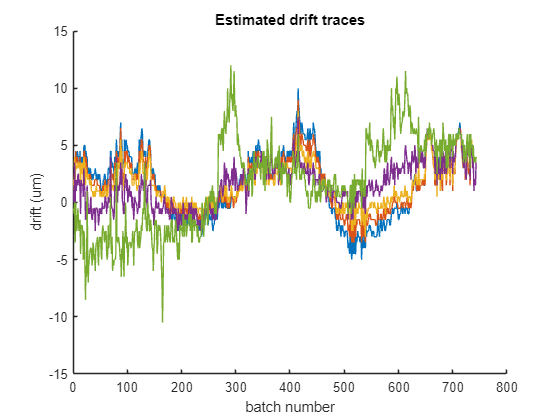

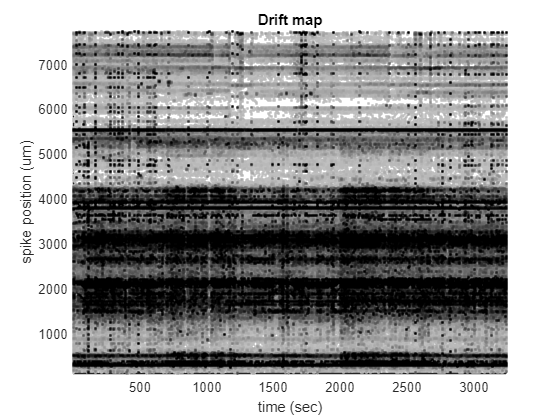

time 789.92, Shifted up/down 743 batches. 
0.61 sec, 1 batches, 10000 spikes 
55.62 sec, 101 batches, 1010000 spikes 
110.05 sec, 201 batches, 2010000 spikes 
164.40 sec, 301 batches, 3010000 spikes 
219.31 sec, 401 batches, 4010000 spikes 
274.65 sec, 501 batches, 5008977 spikes 
329.37 sec, 601 batches, 6008977 spikes 
384.24 sec, 701 batches, 7008872 spikes 
407.37 sec, 743 batches, 7428872 spikes 
time 0.00, GROUP 1/384, units 0 
time 2.22, GROUP 6/384, units 12 
time 4.04, GROUP 11/384, units 20 
time 5.53, GROUP 16/384, units 28 
time 7.16, GROUP 21/384, units 37 
time 9.12, GROUP 26/384, units 47 
time 12.20, GROUP 31/384, units 59 
time 14.17, GROUP 36/384, units 69 
time 15.65, GROUP 41/384, units 77 
time 17.26, GROUP 46/384, units 84 
time 19.46, GROUP 51/384, units 94 
time 23.47, GROUP 56/384, units 107 
time 25.11, GROUP 61/384, units 116 
time 26.87, GROUP 66/384, units 126 
time 27.79, GROUP 71/384, units 131 
time 35.15, GROUP 76/384, units 158 
time 39.84, GROUP 81/38

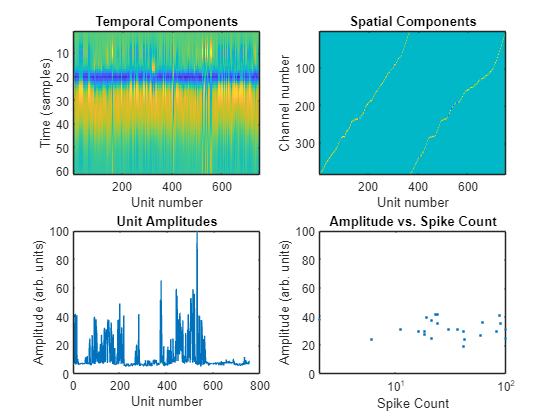

time 0.00, GROUP 1/384, units 0 
time 0.01, GROUP 6/384, units 0 
time 0.02, GROUP 11/384, units 0 
time 0.02, GROUP 16/384, units 0 
time 0.03, GROUP 21/384, units 0 
time 0.03, GROUP 26/384, units 0 
time 0.04, GROUP 31/384, units 0 
time 0.05, GROUP 36/384, units 0 
time 0.05, GROUP 41/384, units 0 
time 0.06, GROUP 46/384, units 0 
time 0.06, GROUP 51/384, units 0 
time 0.07, GROUP 56/384, units 0 
time 0.07, GROUP 61/384, units 0 
time 0.08, GROUP 66/384, units 0 
time 0.09, GROUP 71/384, units 0 
time 0.10, GROUP 76/384, units 0 
time 0.11, GROUP 81/384, units 0 
time 0.12, GROUP 86/384, units 0 
time 0.13, GROUP 91/384, units 0 
time 0.13, GROUP 96/384, units 0 
time 5.04, GROUP 101/384, units 16 
time 9.09, GROUP 106/384, units 28 
time 12.34, GROUP 111/384, units 40 
time 15.01, GROUP 116/384, units 51 
time 18.87, GROUP 121/384, units 67 
time 22.27, GROUP 126/384, units 80 
time 25.46, GROUP 131/384, units 89 
time 29.95, GROUP 136/384, units 100 
time 34.06, GROUP 141/384, 

ans = 137

initialized spike counts
merged 247 into 235 
merged 488 into 474 
merged 406 into 402 
merged 478 into 481 
merged 494 into 476 
merged 482 into 490 
merged 330 into 325 
merged 477 into 475 
merged 354 into 344 
merged 349 into 353 
merged 384 into 387 
merged 474 into 475 
merged 486 into 490 
merged 500 into 470 
merged 379 into 389 
merged 385 into 389 
merged 517 into 513 
merged 138 into 132 
merged 130 into 140 
merged 363 into 375 
merged 4 into 7 
merged 238 into 248 
merged 359 into 342 
merged 399 into 401 
merged 403 into 401 
merged 372 into 382 


ans = 114

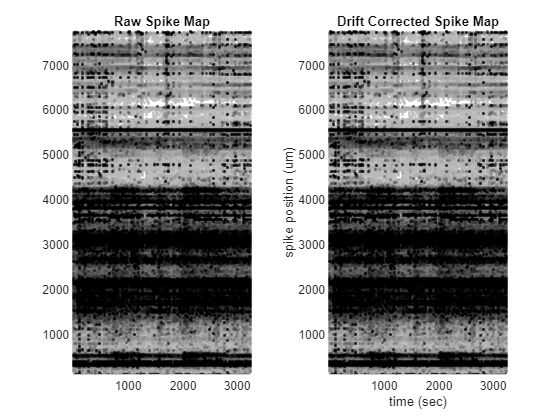

ans = struct with fields:
                ops: [1×1 struct]
                 xc: [384×1 double]
                 yc: [384×1 double]
            xcoords: [384×1 double]
            ycoords: [384×1 double]
               Wrot: [384×384 double]
               temp: [1×1 struct]
              wTEMP: [61×6 single]
               wPCA: [61×6 single]
                 iC: [16×384 gpuArray]
               dist: [10×3452 single]
              iorig: [743×1 double]
             dshift: [743×5 double]
                st0: [4325767×6 double]
                  F: [1534×20×743 double]
                 F0: [1534×20 gpuArray]
                F0m: [1534×20 gpuArray]
               ycup: [100 100 100 100 100 110 110 110 110 110 120 120 120 130 130 130 130 130 140 140 140 140 140 150 150 150 150 150 160 160 160 170 170 170 170 170 180 180 180 180 180 190 190 190 190 190 200 200 200 210 210 210 210 … ] (1×3452 double)
               xcup: [-8 0 8 16 24 -8 0 8 16 24 8 16 24 -8 0 8 16 24 -8 0 8 16 24 -8 0 8 

% 14662
path_to_rec_dir = dir(fullfile(data_dir,'ephys','*.rec','14662','*merged.rec')); path_to_rec_dir = path_to_rec_dir.folder;
probeNum = 1;
numChannels = 384;
runKilosort3(path_to_rec_dir,'probeNum',probeNum,'numChannels',numChannels)


disp('kilosort finished!')

kilosort finished!


## Preprocessing of cdp data

### Data directory

% cdp
cdp_dir = dir(fullfile(data_dir,'cdp','*cdp*.txt')); cdp_path = fullfile(cdp_dir.folder,cdp_dir.name);
% serial number
serial_dir = dir(fullfile(data_dir,'*Serial_numbers*')); serial_path = fullfile(serial_dir.folder,serial_dir.name);
% cortex
cortex_dir  =   dir(fullfile(data_dir,'cortex','*c3d'));
cortex_file =   fullfile(cortex_dir.folder,cortex_dir.name);
% reward
reward_dir  =   dir(fullfile(data_dir,'reward','*.mat'));

% experiment info
load('exp_info.mat')
n_session = size(reward_session,1);
reward_summary = cell(n_session,4);
for i = 1:n_session
    for fd = 1:4
        fl = reward_session(i,fd);
        if fl ~= 0
            reward_summary{i,fd} = reward_list{fl};
        end
    end
end
reward_summary

### Preprocess the cdp data

Extract the tag data from the raw cdp data by the *ExtractCdp* function. *sync_data(:,8)* is the timestamps interpolated based on the pseudo-Fibonacci TTLs. In this time vector, t=0 is the timing of the 1st pulse of the pseudo-Fibonacci TTLs. Make sure that this time vector will be shifted for 1.05 sec to set t=0 as the 1st pulse of the 3-sec TTLs.

% Preprocess raw cdp data
cdp_extracted   =   dir(fullfile(res_dir_path,'extracted*cdp*')); % raw cdp data
serial_number   =   load(serial_path); serial_number   =   serial_number'; % serial number of tags
if isempty(cdp_extracted)
    cd(cdp_dir.folder)
    ExtractCdp_AF_TY_v2('cdp',res_dir_path,'Include',serial_number) % Extract cdp data keeping the tag order
    cd(data_dir)
    % Load data
    cdp_extracted   =   dir(fullfile(res_dir_path,'extracted*cdp*'));
    load(fullfile(cdp_extracted.folder,cdp_extracted.name))
elseif length(cdp_extracted) == 1
    disp('Extracted data are found in the directory.')
    load(fullfile(cdp_extracted.folder,cdp_extracted.name))
else
    error('Multiple files with the specified name were found. Check the file name.')
end

Output file is *extracted_YYMMDD_cdp_*.mat* under the "analysis" directory.

### Extract behavior data

The *Process_extracted_cdp* function extract behavioral features from the preprocessed data. The output is *Extracted_Behavior_YYMMDD.mat* under the "Ext_Behavior_YYMMDD_HHMM.mat" directory.

The variable *t* in the output file is the time vector for global time. The global time is set so that t=0 is the timing of the 1st 3-sec TTLs.

% Extract behaviors
beh_dir             =   dir(fullfile(res_dir_path,'Ext_Behavior*','Extracted_Behavior*'));
if isempty(beh_dir)
    cd(res_dir_path)
    Process_extracted_cdp_TY_v0(res_dir_path) % Extract behavioral features
    cd(data_dir)
    % Load data
    beh_dir         =   dir(fullfile(res_dir_path,'Ext_Behavior*','Extracted_Behavior*'));
    load(fullfile(beh_dir.folder,beh_dir.name))
elseif length(cdp_extracted) == 1
    disp('Behavior data are found in the directory.')
    load(fullfile(beh_dir.folder,beh_dir.name))
    disp('Behavior data are loaded.')
else
    error('Multiple files were contained in the directory. Check the file name.')
end

### Extract feeder data

The information related to reward provision is stored in the MATLAB files in the reward directory. These files contain the timings of reward provision, the identity of the bat who landed on feeders, the identity of feeders, etc.

#### Extracting sync signals

Extract the sync and reward information from the c3d file and save them into a MATLAB file.

% Extract synchronization and reward signals from c3d file
analog_dir = dir(fullfile(res_dir_path,'analog_signal.mat'));
if isempty(analog_dir)
    [~,~,AnalogSignals,AnalogFrameRate,~,~,~] = readC3D_analog(cortex_file); % read C3D data. Column 1 = reward, Column 2 = TTL, Column 3 = CDP server
elseif length(analog_dir)==1
    disp('Analog signal data are found.')
    load(fullfile(res_dir_path,'analog_signal.mat'),'AnalogSignals','AnalogFrameRate')
else
    error('Multiple files were contained in the directory. Check the file name.')
end
AnalogSignals = process_analog_signals(AnalogSignals,AnalogFrameRate);